% Plant
A_hor = [-1/t_V,  0, 0, 0, 0;
          cm(1)/I_yz_lookup(1), 0, 0, 0, 0;
          0, 1, 0, 0, 0;
          0, 0, 0, 0, 1;
          0, 0, T_max/m(1), 0, 0];

b_hor = [1/t_V; 0; 0; 0; 0];
Ts_hor = 1/(100);

Rate controller

% Requirments
zeta = 1;
ts2 = 1;
wn = 4/(zeta*ts2);


p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)];

p_z_want = exp(p_s_want*Ts_hor);

% Plant
c_rate = [0, 1, 0, 0, 0];
d_rate = 0;
sysC = ss(A_hor,b_hor,c_rate,d_rate);
% pls = pole(sysC)
% zers = zero(sysC)
sysD_rate = c2d(sysC,Ts_hor,'zoh');

% Controller
Ki = 14.8

Ki = 14.8000

Kp = Ki*11

Kp = 162.8000

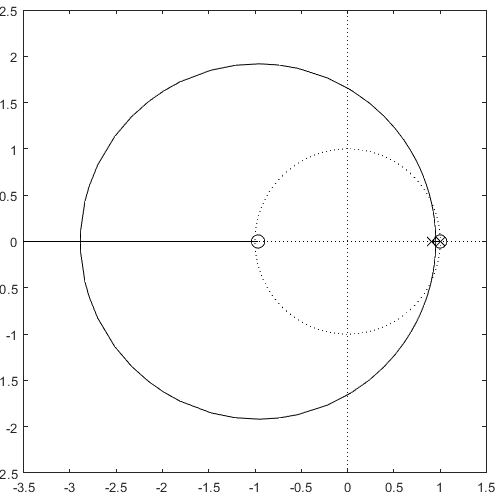

% Ki = 22.39
% Kp = Ki*8.9
C_rate = pid(Kp,Ki,0,0,Ts_hor);
% [C_rate,info] = pidtune(sysD_rate,'PI')

sysFB = feedback(C_rate*sysD_rate,1);
P_cl = rlocus(sysFB,1);
black_rlocus(sysD_rate,[])

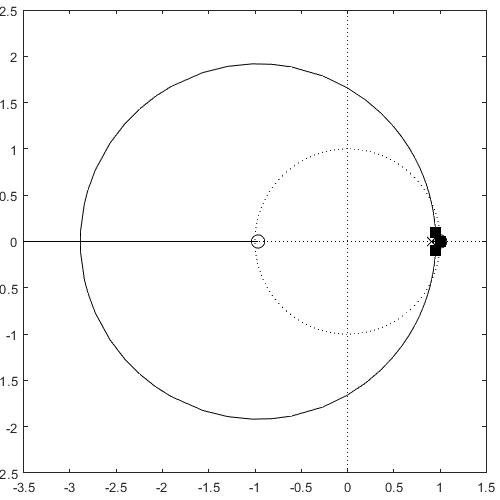

black_rlocus(C_rate*sysD_rate,P_cl)

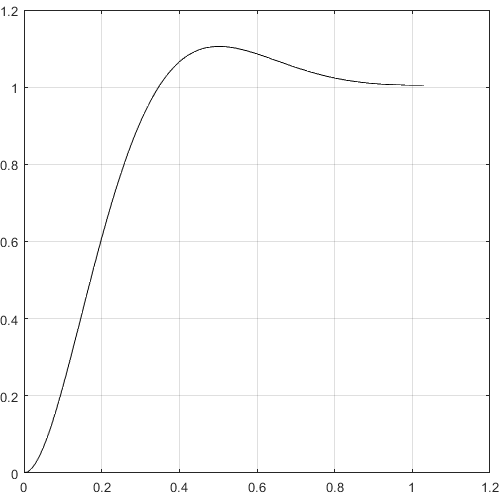

black_step(sysFB)


% Equivalent plant
A_rate = [A_hor-b_hor*C_rate.Kp*c_rate, b_hor*C_rate.Ki;
         -c_rate              , 0];
b_rate = [b_hor*C_rate.Kp;1];

Angle controller

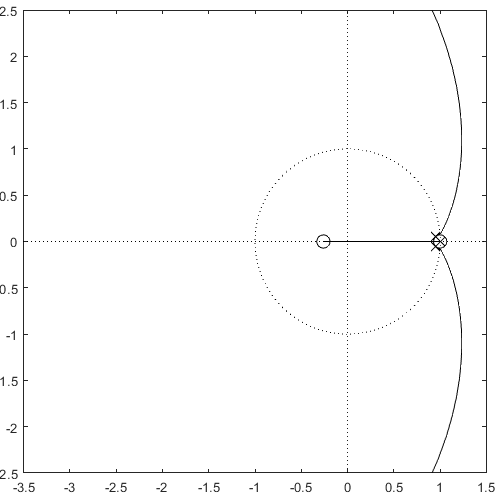

% Requirments
zeta = 1;
ts2 = 1;
wn = 4/(zeta*ts2);

p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)];

p_z_want = exp(p_s_want*Ts_hor);

% Plant
c_ang = [0, 0, 1, 0, 0, 0];
d_ang = 0;
sysC = ss(A_rate,b_rate,c_ang,d_ang);
% pls = pole(sysC)
% zers = zero(sysC)
sysD_ang = c2d(sysC,Ts_hor,'zoh');

% Controller
Kp = 2.25;
C_ang = pid(Kp,0,0,0,Ts_hor);
% [C_ang,info] = pidtune(sysD_ang,'P')

sysFB = feedback(C_ang*sysD_ang,1);
P_cl = rlocus(sysFB,1);
black_rlocus(sysD_ang,[])

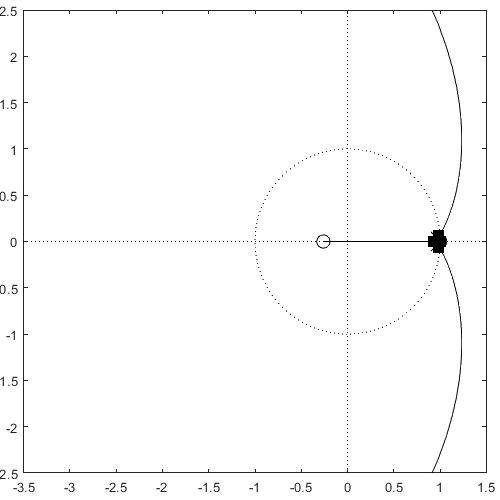

black_rlocus(C_ang*sysD_ang,P_cl)

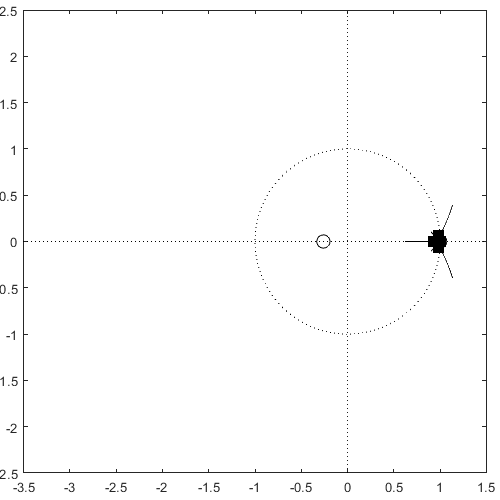

black_rlocus_fine(C_ang*sysD_ang,P_cl)

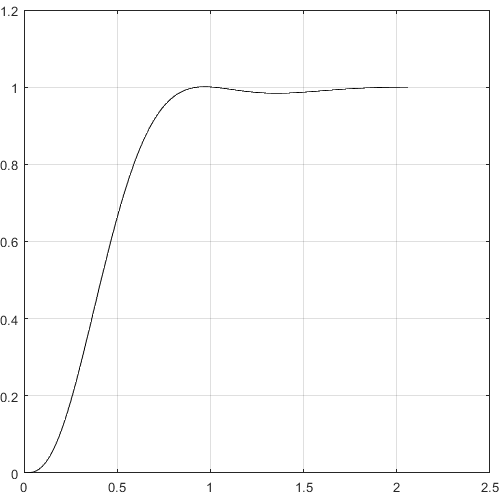

black_step(sysFB)


% Equivalent plant
A_ang = A_rate - b_rate*C_ang.Kp*c_ang;
b_ang = b_rate*(C_ang.Kp/T_max);

 Velocity controller

% Requirments
zeta = 1;
ts2 = 3;
wn = 4/(zeta*ts2);

p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)];

p_z_want = exp(p_s_want*Ts_hor);

% Plant
c_vel = [0, 0, 0, 0, 1, 0];
d_vel = 0;

sysC = ss(A_ang,b_ang,c_vel,d_vel);
% pls = pole(sysC)
% zers = zero(sysC)
sysD_vel = c2d(sysC,Ts_hor,'zoh');

% Controller

Ki = 1

Ki = 1

Kp = Ki*82

Kp = 82

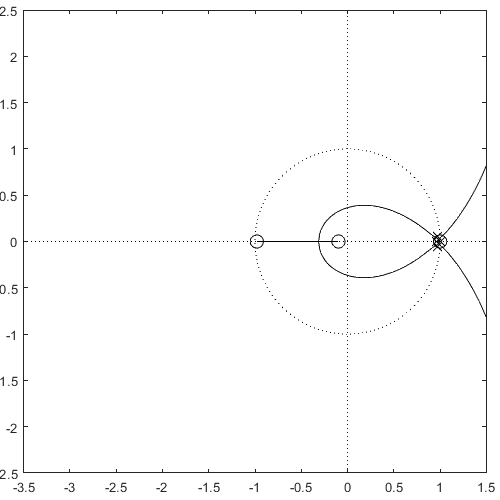

% Ki = 8.6063
% Kp = Ki*5.7
C_vel = pid(Kp,Ki,0,0,Ts_hor);
% [C_vel,info] = pidtune(sysD_vel,'PI',1)
sysFB = feedback(C_vel*sysD_vel,1);
P_cl = rlocus(sysFB,1);
black_rlocus(sysD_vel,[])

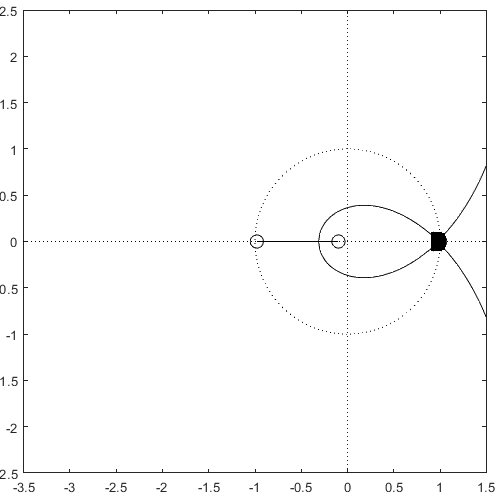

black_rlocus(C_vel*sysD_vel,P_cl)

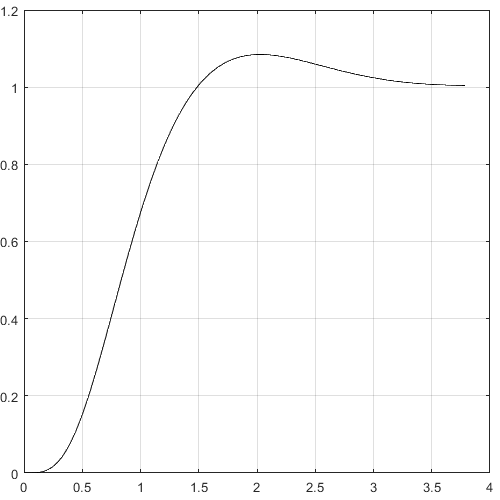

black_step(sysFB)


% Equivalent plant
A_vel = [A_ang-b_ang*C_vel.Kp*c_vel, b_ang*C_vel.Ki;
         -c_vel              , 0];
b_vel = [b_ang*C_vel.Kp;1];

Position controller

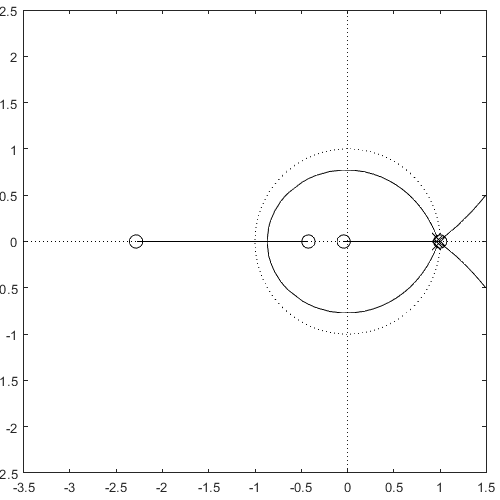

% Requirments
zeta = 1;
ts2 = 5;
wn = 4/(zeta*ts2);

p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)];

p_z_want = exp(p_s_want*Ts_hor);

% Plant
c_pos = [0, 0, 0, 1, 0, 0, 0];
d_pos = 0;

sysC = ss(A_vel,b_vel,c_pos,d_pos);
% pls = pole(sysC)
% zers = zero(sysC)
sysD_pos = c2d(sysC,Ts_hor,'zoh');

% Controller
Kp = 0.52;
C_pos = pid(Kp,0,0,0,Ts_hor);
sysFB = feedback(C_pos*sysD_pos,1);
P_cl = rlocus(sysFB,1);
black_rlocus(sysD_pos,[])

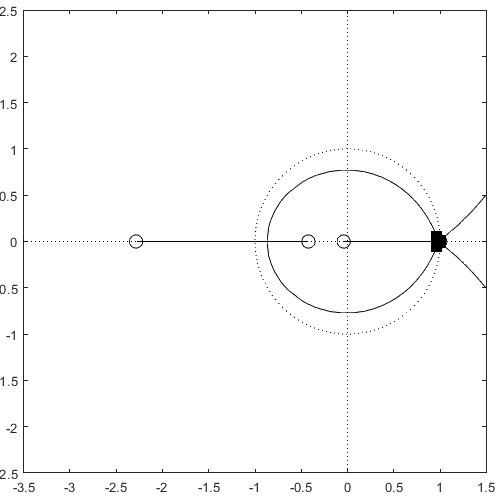

black_rlocus(C_pos*sysD_pos,P_cl)

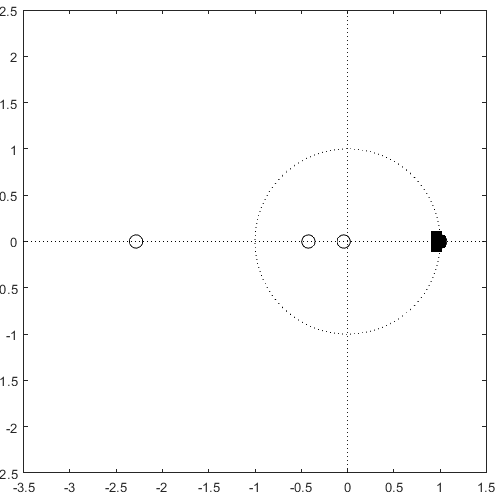

black_rlocus_fine(C_pos*sysD_pos,P_cl)

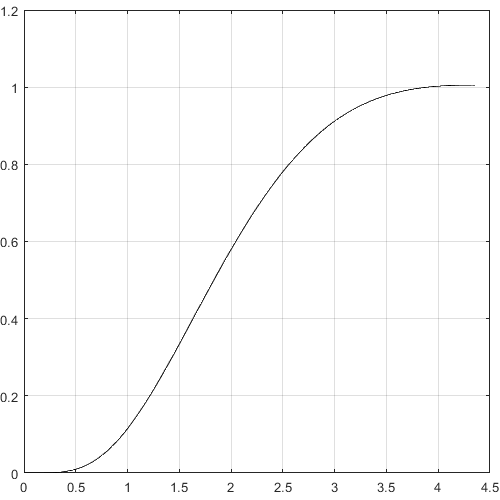

black_step(sysFB)